forkrightv3_0 = readtable("fork_right_v3.0.csv");
masterrightv3_0 = readtable("master_right_v3.0.csv");
v3_0difference = forkrightv3_0.Variables - masterrightv3_0.Variables

v3_0difference =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


#### Difference between v3.0 urdf and forked code

RightTable = readtable('icubarm_right_v3.0_urdf_dhparams.csv');
v3_0urdfvsfork = forkrightv3_0{:, 1:end-2} - RightTable{:, 1:end-2}

v3_0urdfvsfork =      -1.38777878078145e-17                         0                         0                         0
                         0                         0                       180                      -180
       -0.0608224327866823      6.62333263234949e-09          150.978350562544      1.29665333759021e-05
     -1.34107274951501e-07       -0.0183947761443457          179.999970979092          3.07950846619555
      6.42748663215389e-07      0.000649898655228222     -3.58136979627943e-06         -184.499988080491
       -0.0206499276114585      2.60946146357632e-07         -180.000000006274         -195.000016707494
     -0.000340572062272984       0.00258818649548722     -6.27387919394096e-09                       180
      -0.00401493918891312      1.42527199958886e-07           180.00000358137         -179.999983292506
       -2.058996031366e-10      1.71761178246656e-07          180.000016707494     -6.27174756573368e-09
                    0.0625       0.009

## Instantiate Left Right CAD Arms

Compare CAD arms poses

LeftTable = readtable('icubarm_left_v3.0_urdf_dhparams.csv');
LeftTable.Properties.VariableNames = {'a', 'd', 'alpha', 'offset', 'min', 'max'};
LeftArm = Revolute('d', LeftTable.d(1), 'a', LeftTable.a(1), 'alpha', deg2rad(LeftTable.alpha(1)), 'offset', deg2rad(LeftTable.offset(1)));
for i=2:height(LeftTable)
   LeftArm = LeftArm + Revolute('d', LeftTable.d(i), 'a', LeftTable.a(i), 'alpha', deg2rad(LeftTable.alpha(i)), 'offset', deg2rad(LeftTable.offset(i)));
end
LeftArm.name = 'Left';

homtable = readtable('icubarm_left_v3.0_urdf_h0_hn.txt');
h = zeros(4,4);
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{1, k};
        k = k+1;
    end
end
LeftArm.base = h;
                
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{2, k};
        k = k+1;
    end
end
LeftArm.tool = h;


RightTable = readtable('icubarm_right_v3.0_urdf_dhparams.csv');
RightTable.Properties.VariableNames = {'a', 'd', 'alpha', 'offset', 'min', 'max'};
RightArm = Revolute('d', RightTable.d(1), 'a', RightTable.a(1), 'alpha', deg2rad(RightTable.alpha(1)), 'offset', deg2rad(RightTable.offset(1)));
for i=2:height(RightTable)
   RightArm = RightArm + Revolute('d', RightTable.d(i), 'a', RightTable.a(i), 'alpha', deg2rad(RightTable.alpha(i)), 'offset', deg2rad(RightTable.offset(i)));
end
RightArm.name = 'Right';


homtable = readtable('icubarm_right_v3.0_urdf_h0_hn.txt');
h = zeros(4,4);
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{1, k};
        k = k+1;
    end
end
RightArm.base = h;
                
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{2, k};
        k = k+1;
    end
end
RightArm.tool = h;


qdes1 = [0 0 0 0 0 0 60.5 0 0 0];
qdes2 = [0 0 0 0 0 0 90.5 0 0 0];
qdes3 = [0 0 0 0 135 0 90.5 0 0 0];
qdes4 = [0 0 0 0 135 0 90.5 -90 -30.6 20.4];
qdes5 = [25 0 -9.6, 9.45 160.80 79.56 19.005 0 0 0.6];
qdes6 = [25 10 -9.6, 9.45 160.80 79.56 19.005 0 0 0.6];
qdes7 = [25 -15 -9.6, 9.45 160.80 79.56 19.005 0 0 5];
qdes8 = [-25 30 -9.6, 9.45 160.80 79.56 19.005 0 10 5];

Q = deg2rad(qdes1);
RightArm.display

 
RightArm = 
 
Right:: 10 axis, RRRRRRRRRR, stdDH, fastRNE                        
+---+-----------+-----------+-----------+-----------+-----------+  
| j |     theta |         d |         a |     alpha |    offset |  
+---+-----------+-----------+-----------+-----------+-----------+  
|  1|         q1|          0|     0.0725|    -1.5708|          0|  
|  2|         q2|          0|         -0|    -1.5708|     1.5708|  
|  3|         q3|  -0.161133|  0.0304112|   -1.31753|    2.87979|  
|  4|         q4|  -0.145583|1.34107e-07|    -1.5708|   -1.62454|  
|  5|         q5|-0.000649899|-6.42749e-07|    -1.5708|    1.39626|
|  6|         q6|    -0.2005| 0.00999993|     1.5708|     1.5708|  
|  7|         q7|0.000500004|  0.0149999|     1.5708|   -3.14159|  
|  8|         q8|    -0.1628| 0.00200744|    -1.5708|     1.5708|  
|  9|         q9|-1.71761e-07|  2.059e-10|    -1.5708|     1.5708| 
| 10|        q10| 0.00699939|         -0|     1.5708|    -1.5708|  
+---+-----------+-----------+---


LeftArm.display

 
LeftArm = 
 
Left:: 10 axis, RRRRRRRRRR, stdDH, fastRNE                        
+---+-----------+-----------+-----------+-----------+-----------+ 
| j |     theta |         d |         a |     alpha |    offset | 
+---+-----------+-----------+-----------+-----------+-----------+ 
|  1|         q1|          0|     0.0725|    -1.5708|          0| 
|  2|         q2|          0|         -0|    -1.5708|     1.5708| 
|  3|         q3|  -0.161133|  0.0304112|   -1.82406|   -2.87979| 
|  4|         q4|   0.145583|-2.4076e-08|     1.5708|   -1.62454| 
|  5|         q5|0.000649899|-5.59356e-08|     1.5708|    1.39626|
|  6|         q6|     0.2005| 0.00999993|    -1.5708|     1.5708| 
|  7|         q7|-0.000500004|  0.0149999|    -1.5708|   -3.14159|
|  8|         q8|     0.1628|  0.0020069|     1.5708|     1.5708| 
|  9|         q9|-0.000299893|9.64062e-10|     1.5708|     1.5708|
| 10|        q10|-0.00699939|         -0|     1.5708|    -1.5708| 
+---+-----------+-----------+-----------+------

LH_cad = LeftArm.fkine(Q)

 

LH_cad = 
    0.4111    0.2670   -0.8716    0.1663
   -0.1876    0.9605    0.2058    0.1185
    0.8921    0.0789    0.4450   0.04565
         0         0         0         1


RH_cad = RightArm.fkine(Q)

 

RH_cad = 
    0.4111   -0.2670   -0.8716    0.1662
    0.1876    0.9605   -0.2058   -0.1185
    0.8921   -0.0789    0.4450   0.04539
         0         0         0         1


LeftRightDiff_cad = LH_cad.transl - RH_cad.transl

LeftRightDiff_cad =       0.000122841019320891         0.237012982455517      0.000267832303933749


## Compare Left Right forked arms to check displacement

LeftTable = readtable('fork_left_v3.0.csv');
LeftTable.Properties.VariableNames = {'a', 'd', 'alpha', 'offset', 'min', 'max'};
LeftArm = Revolute('d', LeftTable.d(1), 'a', LeftTable.a(1), 'alpha', deg2rad(LeftTable.alpha(1)), 'offset', deg2rad(LeftTable.offset(1)));
for i=2:height(LeftTable)
   LeftArm = LeftArm + Revolute('d', LeftTable.d(i), 'a', LeftTable.a(i), 'alpha', deg2rad(LeftTable.alpha(i)), 'offset', deg2rad(LeftTable.offset(i)));
end
LeftArm.name = 'Left';

homtable = readtable('icubarm_left_v3.0_urdf_h0_hn.txt');
h = zeros(4,4);
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{1, k};
        k = k+1;
    end
end
LeftArm.base = h;
                
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{2, k};
        k = k+1;
    end
end
LeftArm.tool = h;


RightTable = readtable('fork_right_v3.0.csv');
RightTable.Properties.VariableNames = {'a', 'd', 'alpha', 'offset', 'min', 'max'};
RightArm = Revolute('d', RightTable.d(1), 'a', RightTable.a(1), 'alpha', deg2rad(RightTable.alpha(1)), 'offset', deg2rad(RightTable.offset(1)));
for i=2:height(RightTable)
   RightArm = RightArm + Revolute('d', RightTable.d(i), 'a', RightTable.a(i), 'alpha', deg2rad(RightTable.alpha(i)), 'offset', deg2rad(RightTable.offset(i)));
end
RightArm.name = 'Right';


homtable = readtable('icubarm_right_v3.0_urdf_h0_hn.txt');
h = zeros(4,4);
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{1, k};
        k = k+1;
    end
end
RightArm.base = h;
                
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{2, k};
        k = k+1;
    end
end
RightArm.tool = h;

LH = LeftArm.fkine(Q)

 

LH = 
    0.8704   -0.4924   -0.0000    0.2113
    0.0001    0.0002    1.0000    0.1504
   -0.4924   -0.8704    0.0002   0.01103
         0         0         0         1


RH = RightArm.fkine(Q)

 

RH = 
    0.8704   -0.4924    0.0000    0.2113
   -0.0001   -0.0002    1.0000   -0.1504
   -0.4924   -0.8704   -0.0002   0.01103
         0         0         0         1


LeftRightDiff = LH.transl - RH.transl

LeftRightDiff =      -8.32667268468867e-17         0.300727598497251     -3.46944695195361e-18


## Plot Arms

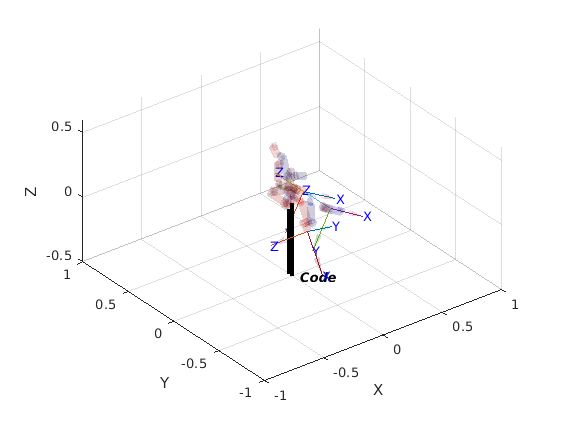

hold on
LeftArm.plot(Q, 'jointcolor', 'b', 'linkcolor', 'r', 'jointdiam', 0.5, ...
    'nojoints', 'workspace', [-1 1 -1 1 -1 1], ...
    'noname', 'noshadow');
    zlim([-1, 1]);

hold on
RightArm.plot(Q, 'jointcolor', 'r', 'linkcolor', 'b', 'jointdiam', 0.5,...
    'nojoints', 'workspace', [-1 1 -1 1 -1 1], ...
    'noname', 'noshadow', 'nobase');
    zlim([-0.5, 0.6]);

## Import Right Arm from forked iKin

Used to compare it with the CAD right arm

RightTableCode = readtable('fork_right_v3.0.csv');
RightTableCode.Properties.VariableNames = {'a', 'd', 'alpha', 'offset', 'min', 'max'};
RightArmCode = Revolute('d', RightTableCode.d(1), 'a', RightTableCode.a(1), 'alpha', deg2rad(RightTableCode.alpha(1)), 'offset', deg2rad(RightTableCode.offset(1)));
for i=2:height(RightTableCode)
   RightArmCode = RightArmCode + Revolute('d', RightTableCode.d(i), 'a', RightTableCode.a(i), 'alpha', deg2rad(RightTableCode.alpha(i)), 'offset', deg2rad(RightTableCode.offset(i)));
end
RightArmCode.name = 'Code';


homtable = readtable('icubarm_right_v3.0_urdf_h0_hn.txt');
h = zeros(4,4);
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{1, k};
        k = k+1;
    end
end
RightArmCode.base = h;
                
k = 2;
for i=1:4
    for j=1:4
        h(i, j) = homtable{2, k};
        k = k+1;
    end
end
RightArmCode.tool = h;

## Plot Arms

hold on
RightArmCode.plot(Q, 'jointcolor', 'b', 'linkcolor', 'r', 'jointdiam', 0.5, ...
    'nojoints', 'workspace', [-1 1 -1 1 -1 1], ...
    'noshadow');
    zlim([-1, 1]);
alpha(0.5)
hold on
RightArm.plot(Q, 'jointcolor', 'r', 'linkcolor', 'b', 'jointdiam', 0.5,...
    'nojoints', 'workspace', [-1 1 -1 1 -1 1], ...
    'noshadow', 'nobase');
    zlim([-0.5, 0.6]);
alpha(0.1)